# **A FDTD for Wave Propagation in a Square**

Here we deal with a 2-D FDTD. The computational domain is now a rectangular region $[0,XL]\times[0,YL]$.

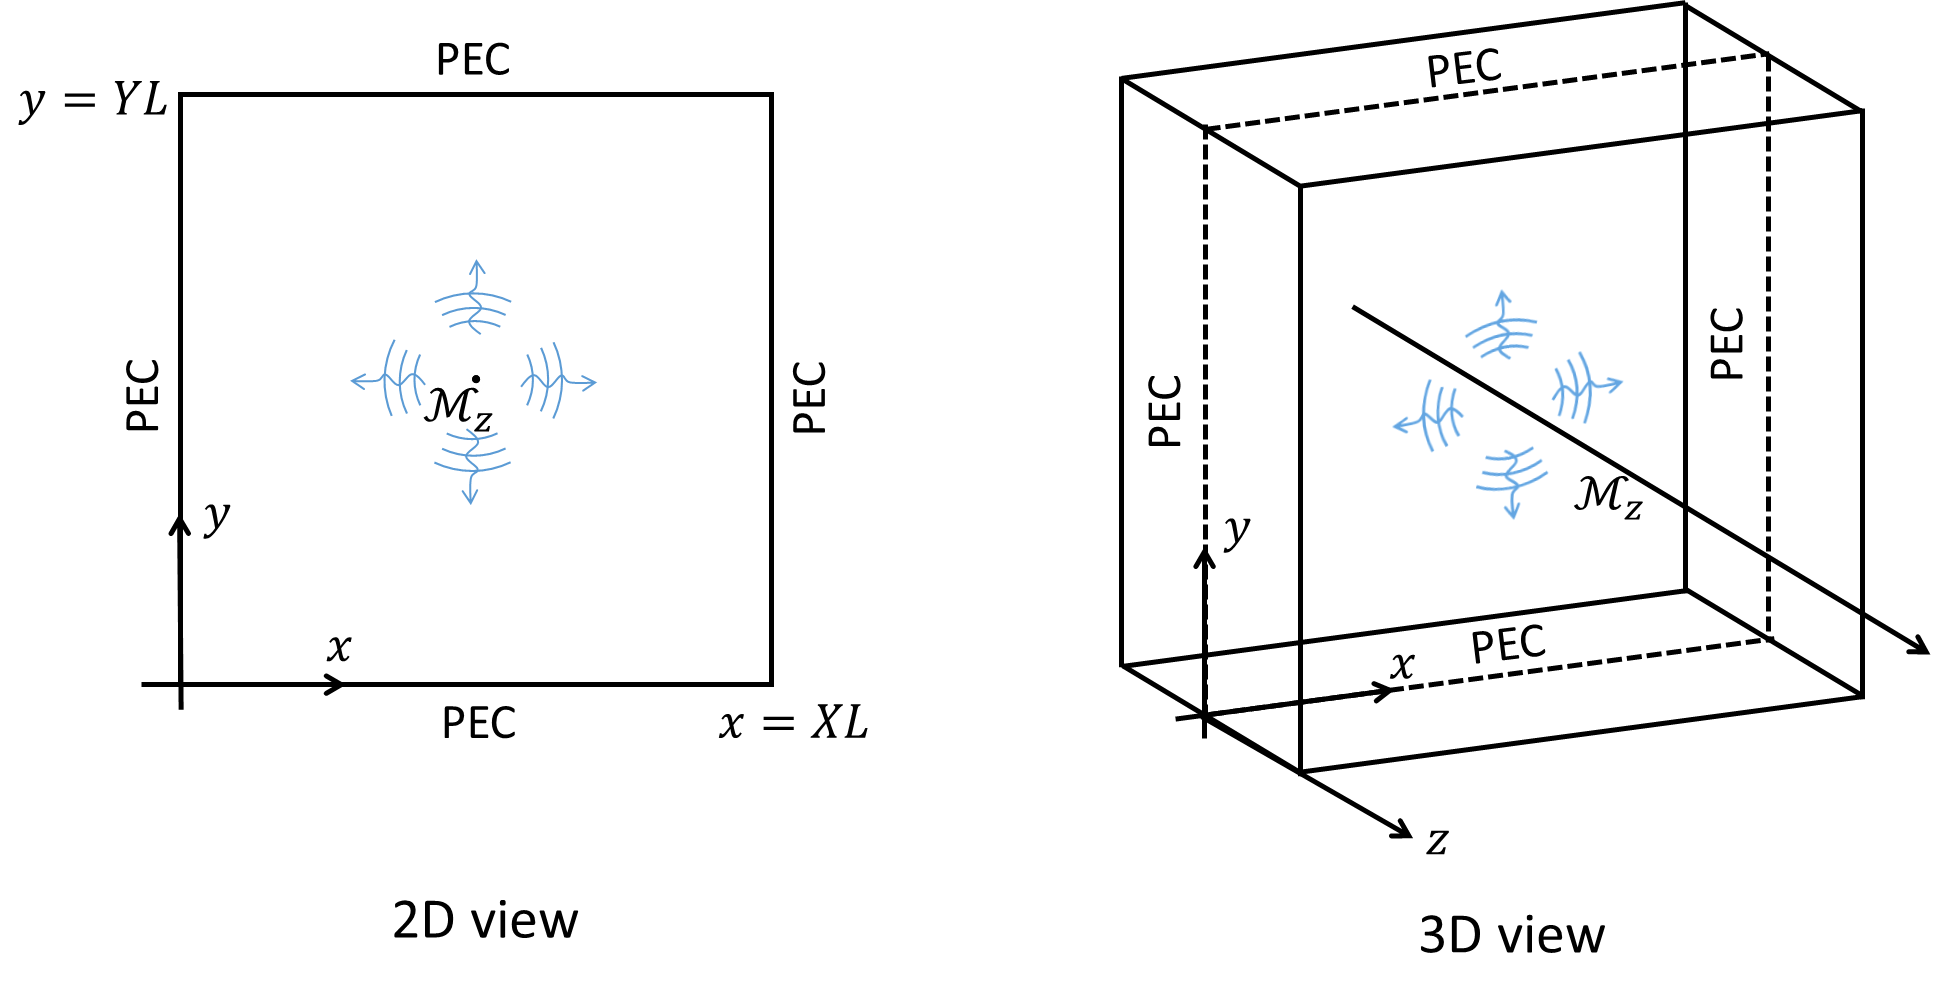

Initial conditions are: E and H fields equal to zero at $t=0$.

Boundary conditions are PEC conditions on all the sides of the rectangle.

We will introduce an impressed magnetic line source in the middle of the rectangle.

Now we have three field components to compute: E_x, E_y, H_z. Each component is sampled on a different spatial grid.

Complete the code where necessary by following the comments.

**Final goal**: save a field animation of the wave excited by the line source.

close all; clearvars

## 1 Definition of fundamental variables

c   = 3d8;               % Speed of light in vacuum
mu0 = 4*pi*1.d-7;        % Vacuum magnetic permeability
eps0= 1.d-9/(36*pi);     % Vacuum dielectric permettivity

f = 30*1d9;              % Frequency of the line source (10 GHz)
lambda = c/f;            % Wavelength in vacuum
sigma = 1; %0; %1;           % Conductivity

## 2 Definition of the spatio-temporal grid

### 2.1 Definition of the spatio-temporal regions

XL = 0.015d0;   % Total length of the domain in the x direction (in meters)
x0 = 0d-3;      % Left boundary along x
YL = 0.015d0;   % Total length of the domain in the y direction (in meters)
y0 = 0d-3;      % Bottom boundary along y
TL = 0.055d-9;  % Duration of the simulation (in seconds)
t0 = 0d-3;      % Initial time

### 2.2 Definition of the spatio-temporal grid

% Discretization
NX=101;    % number of cells along the x direction
NY=101;    % number of cells along the y direction
NT=200;    % number of time intervals
Delta_x=XL/(NX);
Delta_y=YL/(NY);
Delta_t=TL/NT;

% Sampling instants
t_E = t0:Delta_t:TL;     % Define here the sampling instants for the E field
t_H = t0+Delta_t/2:Delta_t:TL-Delta_t;     % Define here the sampling instants for the H field

% Sampling points of Ex
x_Ex= x0+Delta_x/2:Delta_x:XL-Delta_x/2;     % Define here the x sampling points for the Ex field
y_Ex= y0:Delta_y:YL;     % Define here the y sampling points for the Ex field
[y_Ex_grid,x_Ex_grid] = meshgrid(y_Ex,x_Ex);

% Sampling points of Ey
x_Ey= x0:Delta_x:XL;     % Define here the x sampling points for the Ey field
y_Ey= y0+Delta_y/2:Delta_y:YL-Delta_y/2;     % Define here the y sampling points for the Ey field
[y_Ey_grid,x_Ey_grid] = meshgrid(y_Ey,x_Ey);

% Sampling points of Hz
x_Hz= x0+Delta_x/2:Delta_x:XL-Delta_x/2;    % Define here the x sampling points for the Hz field
y_Hz= y0+Delta_y/2:Delta_y:YL-Delta_y/2;    % Define here the y sampling points for the Hz field
[y_Hz_grid,x_Hz_grid] = meshgrid(y_Hz,x_Hz);

## 3 Definition of the impressed line source

Let us define a magnetic line source $M_z(x,y;t)$ placed at the point $x=\frac{XL}{2}$ and  $y = \frac{YL}{2}$. 

This is done with the function "magnetic_current.m" which computes the following field:

    $    M_z = \sin(2 \pi f_0 t)   \quad \text{if } x=\frac{XL}{2} \text{ and } y= \frac{YL}{2}$, in the interval  $0\leq t\leq 1.6571\cdot 10^{-2} \text{ ns}$

with $f_0 = 30 \text{ GHz}$. Notice that the interval $0\leq t\leq 1.6571\cdot 10^{-2} \text{ ns}$ corresponds to the first 58 time samples.

Remember to sample the magnetic source at the correct spatial points and instants. In the code below you should replace 'x points', 'y points', 'time' with the correct variables defined in the Section 2.

Mz(:,:,:) = magnetic_current(x_Hz,y_Hz,t_H,f);

## 4 The FDTD algorithm: the time update with impressed sources

Now we need to apply the time update of ${\rm TE}^z$ 2-D Maxwell equations with the presence of a magnetic source.

Remember in which equation the magnetic current goes. The  equations read:

            
$$\mu_0\frac{\partial}{\partial t}H_z = \frac{\partial}{\partial y}E_x - \frac{\partial}{\partial x}E_y - M_z \\

\varepsilon_0\frac{\partial}{\partial t}E_x = \frac{\partial}{\partial y}H_z \\

\varepsilon_0\frac{\partial}{\partial t}E_y = -\frac{\partial}{\partial x}H_z \\$$


% Initial conditions: initialization of the fields
Ex= zeros(NX, NY+1);   % Initialize to zero the Ex field (a 2-D vector variable)
Ey= zeros(NX+1,NY);   % Initialize to zero the Ey field (a 2-D vector variable)
Hz= zeros(NX, NY);   % Initialize to zero the Hz field (a 2-D vector variable)
 
 
% Definition of the constants for the time update
const_ty_eps =  Delta_t/(eps0*Delta_y);
const_tx_eps =  Delta_t/(eps0*Delta_x);
const_ty_mu  =  Delta_t/(mu0*Delta_y);
const_tx_mu  =  Delta_t/(mu0*Delta_x);
% Definition of the constants for the time update with losses (for Section 5)
const_loss_1 =  (1-sigma*Delta_t/(2*eps0))/(1+sigma*Delta_t/(2*eps0));
const_loss_2 =  1/(1+sigma*Delta_t/(2*eps0));

% Here we prepare the figure parameters to visualize the H_z field in a correct way
hFig = figure(5)

hFig =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


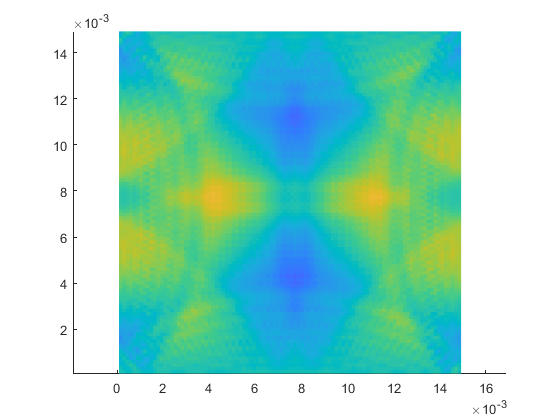

caxis([-1d-8 1d-8]) % Good color scale for the Hz video
hold on
set(gcf,'Visible','on')
axis equal
a = size(Ey(1,:));
b = size(Ex(:,1));
aviobj = VideoWriter('Hz_2D_line_source.avi');
open(aviobj);

for time_instant=1:NT-1
    
    % Boundary conditions on E at x=0 and at x=XL, y=0 and at y=YL 
    Ey(1,:) = zeros(a); Ey(end, :) = zeros(a);
    %Ex(:, 1) = zeros(b); Ex(:, end) = zeros(b);
    % Boundary conditions on H at y = 0 and at y = YL
    Ex(:,1) = Ex(:,1) + 2*const_ty_eps*(Hz(:,1));
    Ex(:,end) = Ex(:,end) - 2*const_ty_eps*(Hz(:,end));
    % E-field time update
    Ex(1:end, 2:end-1) = Ex(1:end, 2:end-1) + const_ty_eps*(Hz(1:end, 2:end)-Hz(1:end, 1:end-1));
    Ey(2:end-1, 1:end) = Ey(2:end-1, 1:end) - const_tx_eps*(Hz(2:end, 1:end)-Hz(1:end-1, 1:end));
    
    % H-field time update
    Hz(1:end,1:end) = Hz(1:end,1:end) + const_ty_mu*(Ex(1:end, 2:end) - Ex(1:end, 1:end-1)) - const_tx_mu*(Ey(2:end, 1:end)-Ey(1:end-1, 1:end)) - Delta_t/mu0*Mz(1:end,1:end,time_instant);
        
% Recording the frames for each field as in
% https://stackoverflow.com/questions/27978938/how-to-generate-a-video-file-using-a-series-of-plots-on-matlab
    %figure(5)
    %h= pcolor(x_Hz_grid,y_Hz_grid,Hz(:,:));
    %set(h, 'EdgeColor', 'none');
    h =pcolor(x_Hz_grid,y_Hz_grid,Hz(:,:));
    set(h, 'EdgeColor', 'none');
    
    %Hz_frames(time_instant) = getframe;
    img = getframe;
    writeVideo(aviobj, img);
    
end

close(aviobj)

% Recording the Hz field animation
%writerObj = VideoWriter('Hz_2D_line_source.avi');
%open(writerObj);
%writeVideo(writerObj, Hz_frames)
%close(writerObj);

## 5 Including losses in the domain

Let us now include a constant conductivity "sigma" $\sigma$ in the computational domain.

The conductivity variable "sigma" is in Section 1 of this file. Try with the case $\sigma=1 \text{ S}$ (for simplicity keep the vacuum dielectric constant, even if not realistic).

You need to modify the FDTD coefficients used in the time update in Section 4 (see slides).

Run again the FDTD and save the new field animation with losses. Can you see a difference in the field propagation?